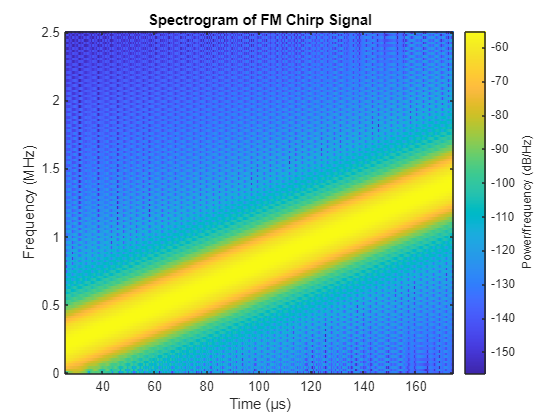

clc; clear; close all

fs = 5e6; % Sampling frequency (5 MHz)
T = 200e-6; % Duration (200 µs)
t = 0:1/fs:T; % Time vector
mu = 4.0e9; % Chirp rate (4 × 10^9)
x = cos(2 * pi * mu * t.^2); % FM Chirp signal
f0 = 0; % Initial Freq (Hz)
% f1 = 2 * mu * T;
% x = chirp(t, f0, T, f1);

% Spectrogram
win = triang(256); % 256-point triangular window
overlap = 255; % Overlap of 255 samples
nfft = 256; % FFT points
spectrogram(x, win, overlap, nfft, fs, 'yaxis');
title('Spectrogram of FM Chirp Signal');

**Definition 1**: From the given form, rewrite: 


$$x(t)=cos (2\pi \mu t2)=cos [2\pi f1(t)t],x(t) = \cos(2\pi \mu t^2) = \cos[2\pi f_1(t) t]$$


where we force the argument to look like $2\pi f1(t)t2 \pi f_1(t) t$.Matching terms:


$$2\pi \mu t2=2\pi f1(t)t  \Longrightarrow   f1(t)=\mu t.2\pi \mu t^2 = 2\pi f_1(t) t \Longrightarrow f_1(t) = \mu t$$


**Definition 2**: Using the derivative of the phase:


$$x(t)=cos [\phi (t)]where \phi (t)=2\pi \mu t2.x(t) = \cos[\phi(t)] \quad \text{where } \phi(t) = 2\pi \mu t^2$$


The instantaneous frequency is: 


$$f2(t)=12\pi ddt[\phi (t)]=12\pi ddt(2\pi \mu t2)=12\pi (4\pi \mu t)=2\mu t.f_2(t) = \frac{1}{2\pi} \frac{d}{dt}[\phi(t)] = \frac{1}{2\pi} \frac{d}{dt}(2\pi \mu t^2) = \frac{1}{2\pi}(4\pi \mu t) = 2\mu t$$
 

**Determining Which Definition Matches the Spectrogram Ridge**

The correct instantaneous frequency is:


$$finst(t)=12\pi d\phi (t)dt=2\mu t.f_{\text{inst}}(t) = \frac{1}{2\pi} \frac{d\phi(t)}{dt} = 2\mu t$$


This matches $f_2(t)$, not $f_1(t)$.Therefore, the ridge observed in the spectrogram will correspond to $f2(t)=2\mu tf_2(t) = 2\mu t$.

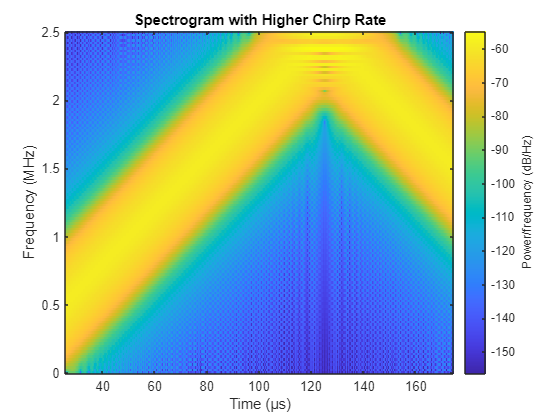

% Modified chirp
mu2 = 1.0e10; % Chirp rate (1 × 10^10)
x2 = cos(2 * pi * mu2 * t.^2);

% Spectrogram
spectrogram(x2, win, overlap, nfft, fs, 'yaxis');
title('Spectrogram with Higher Chirp Rate');

Comparing spectrograms: TODO

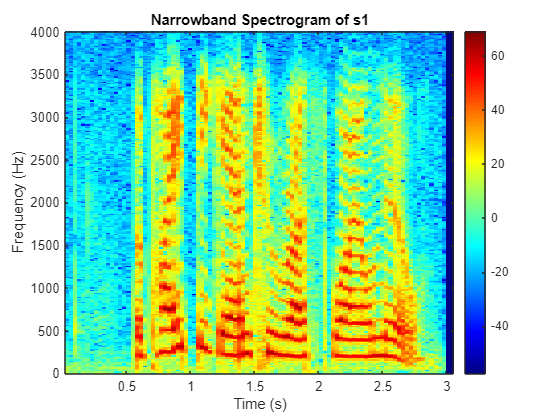

load s1;
load s5;

fs = 8000;  % Sampling frequency

% soundsc(s1, fs);
% pause(length(s1)/fs + 1);
% soundsc(s5, fs);

narrow_window_length = 512;
narrow_overlap = 256;
narrow_fft_length = 512;
narrow_window = triang(narrow_window_length);

% Narrowband spectrogram for s1
[~,F_s1,T_s1,P_s1] = spectrogram(s1, narrow_window, narrow_overlap, narrow_fft_length, fs);
figure;
imagesc(T_s1, F_s1, 10*log10(P_s1)); axis xy; colormap jet; colorbar;
title('Narrowband Spectrogram of s1');
xlabel('Time (s)');
ylabel('Frequency (Hz)');

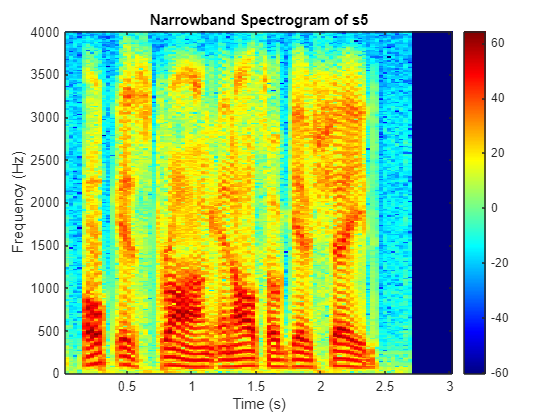

% Narrowband spectrogram for s5
[~,F_s5,T_s5,P_s5] = spectrogram(s5, narrow_window, narrow_overlap, narrow_fft_length, fs);
figure;
imagesc(T_s5, F_s5, 10*log10(P_s5)); axis xy; colormap jet; colorbar;
title('Narrowband Spectrogram of s5');
xlabel('Time (s)');
ylabel('Frequency (Hz)');

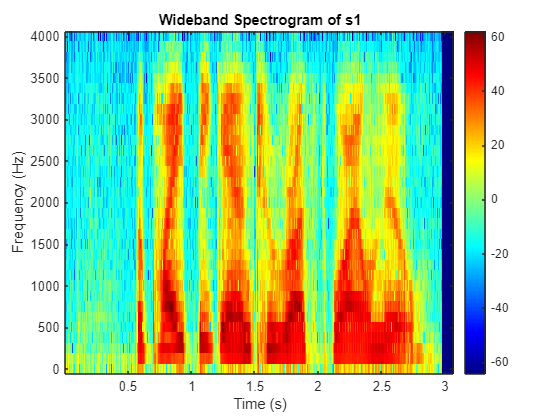

wide_window_length = 64;
wide_overlap = 32;
wide_fft_length = 64;
wide_window = triang(wide_window_length);

% Wideband spectrogram for s1
[~,F_s1_w,T_s1_w,P_s1_w] = spectrogram(s1, wide_window, wide_overlap, wide_fft_length, fs);
figure;
imagesc(T_s1_w, F_s1_w, 10*log10(P_s1_w)); axis xy; colormap jet; colorbar;
title('Wideband Spectrogram of s1');
xlabel('Time (s)');
ylabel('Frequency (Hz)');

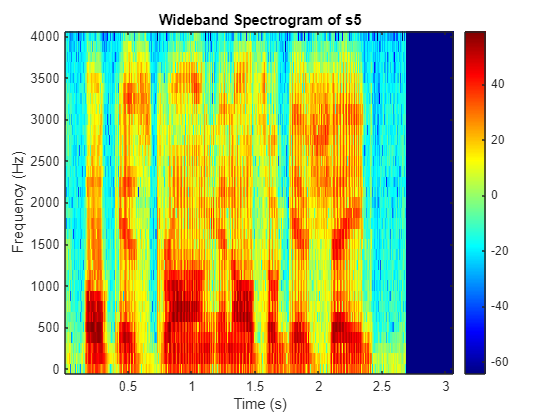

% Wideband spectrogram for s5
[~,F_s5_w,T_s5_w,P_s5_w] = spectrogram(s5, wide_window, wide_overlap, wide_fft_length, fs);
figure;
imagesc(T_s5_w, F_s5_w, 10*log10(P_s5_w)); axis xy; colormap jet; colorbar;
title('Wideband Spectrogram of s5');
xlabel('Time (s)');
ylabel('Frequency (Hz)');

**Observations**:

- In the narrowband spectrograms, the horizontal striations represent individual harmonics. From these, we can estimate the fundamental frequency.

- In the wideband spectrograms, the harmonics smear together and form broad bands. These bands represent the formants. From these, we can estimate the formant frequencies as they vary over time.

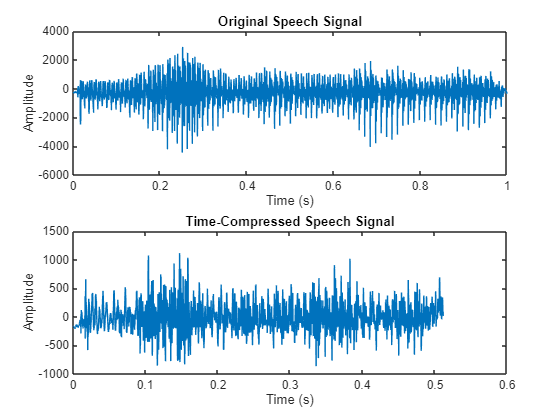

% Load the speech signal
load('vowels.mat');
fs = 8000; % Sampling frequency (Hz)

% Define parameters
winLength = 256;
overlap = 128;
nfft = 1024;
window = rectwin(winLength);

% Compute the STFT
[S,F,T] = spectrogram(vowels, window, overlap, nfft, fs);

% Compress the time scale by taking every other time slice
S_compressed = S(:,1:2:end);

% Reconstruct the time-domain signal
vowels_fast = istft(S_compressed, fs, 'Window', window, 'OverlapLength', overlap, 'FFTLength', nfft);

% Ensure the output is real and double
vowels_fast = real(vowels_fast);

% Plot the original and compressed signals
figure;
subplot(2,1,1);
plot((0:length(vowels)-1)/fs, vowels);
title('Original Speech Signal');
xlabel('Time (s)');
ylabel('Amplitude');

subplot(2,1,2);
plot((0:length(vowels_fast)-1)/fs, vowels_fast);
title('Time-Compressed Speech Signal');
xlabel('Time (s)');
ylabel('Amplitude');

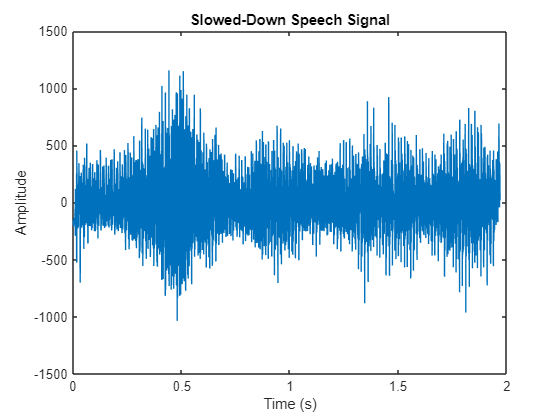

% Listen to the signals
soundsc(vowels, fs);
pause(length(vowels)/fs + 1);
soundsc(vowels_fast, fs);

% Expand the time scale by a factor of 2
% Duplicate each time slice to slow down the sound
S_expanded = interp1(1:size(S, 2), S.', linspace(1, size(S, 2), size(S, 2)*2), 'linear').';

% Reconstruct the time-domain signal
vowels_slow = istft(S_expanded, fs, 'Window', window, 'OverlapLength', overlap, 'FFTLength', nfft);

% Ensure the output is real and double
vowels_slow = double(real(vowels_slow));

figure;
plot((0:length(vowels_slow)-1)/fs, vowels_slow);
title('Slowed-Down Speech Signal');
xlabel('Time (s)');
ylabel('Amplitude');

% Listen to the signals
pause(length(vowels_fast)/fs + 1);
soundsc(vowels_slow, fs);